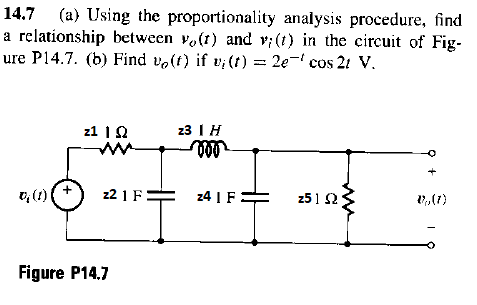

primero expresamos los elementos en terminos de s

clc, clear, close all
format short g
syms s vi t

r = 1;
l = 1;
c = 1;

z1 = 1;
z2 = 1/(s*c);
z3 = l*s;
z4 = 1/(s*c);
z5 = 1;

**a)** Sabemos que la tension en el nodo (que es la misma tension en z2) que une a z1 y z2 esta definida por el siguiente divisor de tension:

v_z2 = simplify(( (1/(1/(1/(1+1/(z2))+z3)+1/z2) )/(z1+(1/(1/(1/(1+1/(z2))+z3)+1/z2)) ))*vi) % [V] tension en z2

$$v\_z2 = \frac{\mathrm{vi}\,\left(s^{2}+s+1\right)}{s^{3}+2\,s^{2}+3\,s+2}$$

Conociendo la tension en dicho nodo, y sabiendo que la tension en z4 y z5 es la misma, podemos realizar otro divisor de tension entre z3 y el paralelo de z4 y z5, tomando como tension de entrada la tension en z2 que calculamos anteriormente.

v0 = simplify(( 1/((1/z5)+(1/z4)) )/( z3 + 1/((1/z5)+(1/z4)) )*v_z2) %[V]

$$v0 = \frac{\mathrm{vi}}{s^{3}+2\,s^{2}+3\,s+2}$$

y asi obtenemos la relacion entre vi y v0.

**b) **

vf = 2*exp(-1*t)*cos(2*t) %[V]

$$vf = 2\,\cos\left(2\,t\right)\,{\mathrm{e}}^{-t}$$

vm = 2;

definimos s

s = -1+j*2

s =            -1 +          2i


Encontramos v0 con la funcion encontrada en el apartado a

v0 = vm/(s^3 + 2*s^2 + 3*s + 2) %[V] complejo

v0 =          0.25 +       0.25i


v0_fasor = [abs(v0) angle(v0)*180/pi] %[V] fasor

v0_fasor =       0.35355           45


v0 = abs(v0)*exp(-1*t)*cos(2*t + 45) %[V] cosenoidal

$$v0 = \frac{\sqrt{2}\,{\mathrm{e}}^{-t}\,\cos\left(2\,t+45\right)}{4}$$